# EE-414 Speech Processing Lab

#  Lab-3

## Aim 

#### ● To identify optimal sampling frequency for speech signal processing.

#### ● To identify optimal bit resolution for speech signal processing. 

#### ● To understand the significance of telephone bandwidth. 

#### ● To understand the difference between narrowband and wideband speech. 

## Introduction:

The speech signals that we give as input is analog in nature hence there is a need to convert it into the digital form so that we can do digital speech processing techniques. Hence sampling and storing the speech signal is necessary inorder to work in digital domain. Intelligibility, quantity and quality of information also depend on the sampling rate and bit resolution, hence it is important to understand the two parameters.

## A. Study of Sampling Frequency 

-  Record the word ‘Speech’ using a sampling frequency of 44.1kHz save it in a .wav file. Plot the complete speech signal and the frequency spectrum for different sounds. 

- Resample the above speech signal to 16kHz and plot the complete speech signal along with the frequency spectra for different sounds. Comment on the intelligibility of the speech signal sampled at 16kHz as compared to the speech signal sampled at 44.1kHz and whether this is a good choice for the sampling frequency. 

- Resample the speech signal obtained from (a) to 8kHz and plot the complete speech signal along with the frequency spectra for different sounds. Comment on the intelligibility of the speech signal sampled at 8kHz comparing it to the above signals and whether this is a good choice for the sampling frequency. 

- Resample the speech signal obtained from (a) to 4kHz and plot the complete speech signal along with the frequency spectra for different sounds. Comment on the intelligibility of the speech signal sampled at 4kHz comparing it to the above signals and whether this is a good choice for the sampling frequency.

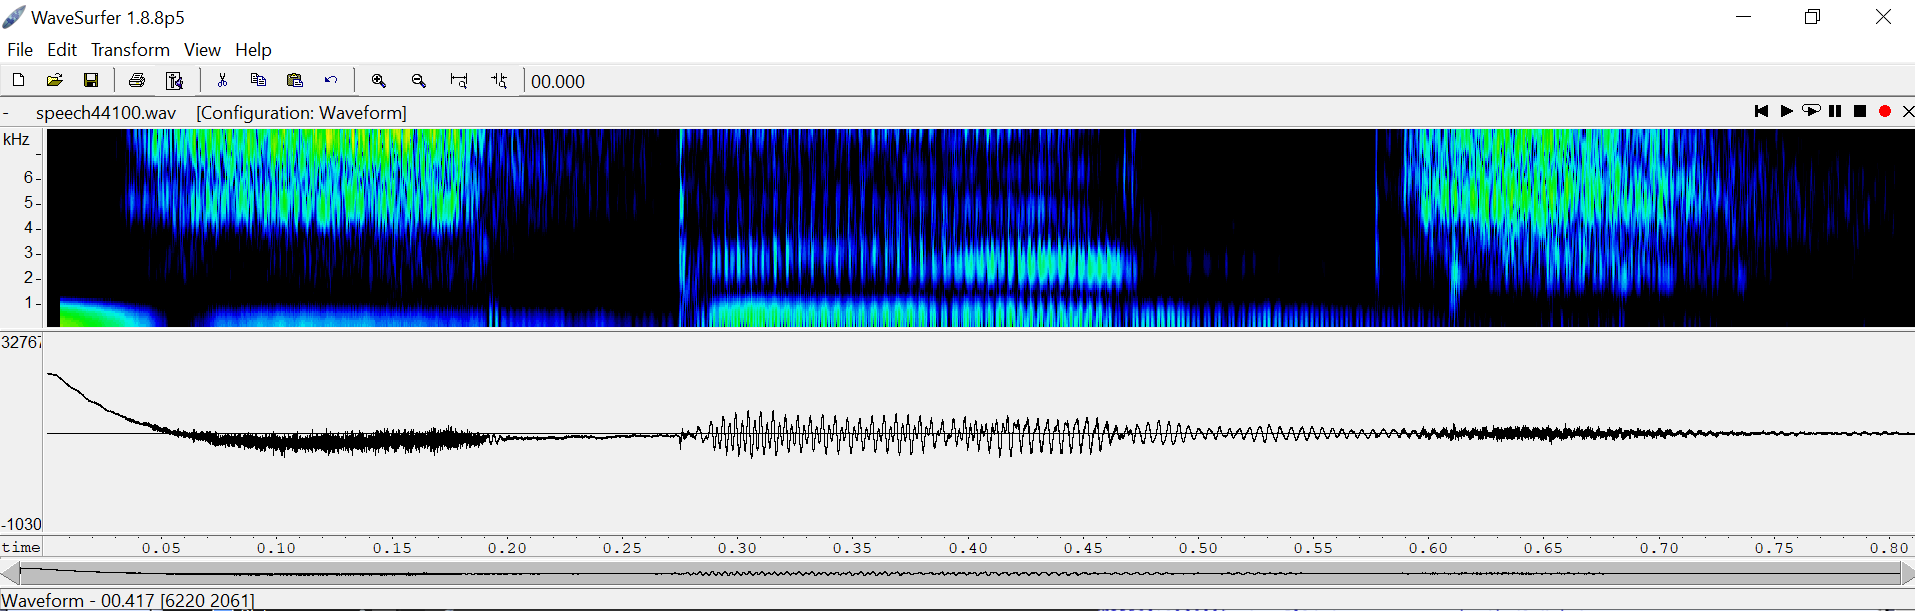

### Theory:

Sampling rate is kept according to the Nyquist theorem, which states that the sampling frequency must be greater than twice the maximum frequency component of a signal. Which means that fs > 2 fm, where fs is sampling frequency and fm is the max frequency component.of the signal. Since our speech signals vary from 20 Hz to 20 kHz, we keep a sampling rate of 44.1 kHz which means that maximum frequency of signals is 22.05 kHz (takes some tolerance into account). Lower sample rates (16 kHz, 8 kHz) are used when the maximum frequency components are not very large, which will reduce computational costs.

### Procedure:

We first record the word "Speech", using software *Audacity* with sampling rate of 44.1 kHz and store it as a wave file.  Then we plot time domain signal for whole signal and frequency spectrum for the sounds "ss", "p", "ee" and "ch". We then repeat this process by resampling the original 44.1 kHz to 16 kHz, 8 kHz and 4 kHz and repeat the process of plotting the time and frequency domain plots. We do resampling by using the inbuilt matlab function *resample(x, p, q)*, which resamples signal x at p/q times the original sample rate.

### Code and Plots:

**1. 44.1 kHz**

close all; clc; clear all;

[y,fs]=audioread('speech44100.wav'); 
sound(y, 44100);

y = y(:,2); % Taking right channel
% "Speech" 
plot_time_signal(y, fs, '"Speech" 44100 hz time signal'); 

% ss (Fricative, Sibilant)
plot_time_signal(y(int64(0.07*fs):int64(0.19*fs)), fs, '"ss" 44100 hz time signal');

Operation terminated by the user.

Error in matlab.internal.editor.figure.FigureDataTransporter

Error in matlab.internal.editor.figure.FigureDataTransporter.getFigureData

Error in matlab.internal.editor.figure.FigureDataTransporter.getFigureMetaData

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager.saveSnapshot

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager.figureBeingCleared

Error in matlab.graphics.internal.clearNotify (line 32)
        matlab.internal.editor.FigureManager.figureBeingCleared(fig, flag);

Error in claNotify

Error in <a href="matl

plot_freq_spectrum(y(int64(0.07*fs):int64(0.19*fs)), fs, '"ss" 44100 hz spectrum');

% p (UU, Plosives)
plot_time_signal(y(int64(0.2744*fs):int64(0.2818*fs)), fs, '"p" 44100 hz time signal');
plot_freq_spectrum(y(int64(0.2744*fs):int64(0.2818*fs)), fs, '"p" 44100 hz spectrum');

% ee (Vowel)
plot_time_signal(y(int64(0.305*fs):int64(0.460*fs)), fs, '"ee" 44100 hz time signal');
plot_freq_spectrum(y(int64(0.305*fs):int64(0.460*fs)), fs, '"ee" 44100 hz spectrum');

% ch (affricate)
plot_time_signal(y(int64(0.625*fs):int64(0.7*fs)), fs, '"ch" 44100 hz time signal');
plot_freq_spectrum(y(int64(0.625*fs):int64(0.7*fs)), fs, '"ch" 44100 hz spectrum');


**2. 16 kHz**

f = 16000;
[P,Q] = rat(f/fs);
y_resampled = resample(y,P,Q);
sound(y_resampled, f);

% "Speech" 
plot_time_signal(y_resampled, f, ['"Speech" ',   num2str(f) ,'hz time signal']); 

% ss (Fricative, Sibilant)
plot_freq_spectrum(y_resampled(int64(0.07*f):int64(0.19*f)), f, ['"ss" ',  num2str(f), 'hz Frequency spectrum']);

% p (UU, Plosives)
plot_freq_spectrum(y_resampled(int64(0.2744*f):int64(0.2818*f)), f,  ['"p" ',  num2str(f), 'hz Frequency spectrum']);

% ee (Vowel)
plot_freq_spectrum(y_resampled(int64(0.305*f):int64(0.460*f)), f,  ['"ee" ',  num2str(f), 'hz Frequency spectrum']);

% ch (affricate)
plot_freq_spectrum(y_resampled(int64(0.625*f):int64(0.7*f)), f, ['"ch" ',  num2str(f), 'hz Frequency spectrum']);

**Comments:**The speech is fairly clear and audible. We are able to identify the word as "speech". This sampling rate is a good choice. The speech signal sampled at this rate is known as wideband speech signal

**3. 8 kHz**

f = 8000;
[P,Q] = rat(f/fs);
y_resampled = resample(y,P,Q);
sound(y_resampled, f);

% "Speech" 
plot_time_signal(y_resampled, f, ['"Speech"',   num2str(f) ,'hz time signal']); 

% ss (Fricative, Sibilant)
plot_freq_spectrum(y_resampled(int64(0.07*f):int64(0.19*f)), f, ['"ss" ',  num2str(f), 'hz Frequency spectrum']);

% p (UU, Plosives)
plot_freq_spectrum(y_resampled(int64(0.2744*f):int64(0.2818*f)), f,  ['"p" ',  num2str(f), 'hz Frequency spectrum']);

% ee (Vowel)
plot_freq_spectrum(y_resampled(int64(0.305*f):int64(0.460*f)), f,  ['"ee" ',  num2str(f), 'hz Frequency spectrum']);

% ch (affricate)
plot_freq_spectrum(y_resampled(int64(0.625*f):int64(0.7*f)), f, ['"ch" ',  num2str(f), 'hz Frequency spectrum']);

**Comments:**The sound is a bit muddled but we are able to identify the sound as "speech". This is not a very good choice but if needed, it does the task. The telephone bandwidth is having max cutoff frequency as 3.3 kHz so an 8 kHz sampling frequency was used for this purpose. The speech signal with this sampling rate is known as narrowband speech. 

**4. 4kHz**

f = 4000;
[P,Q] = rat(f/fs);
y_resampled = resample(y,P,Q);
sound(y_resampled, f);

% "Speech" 
plot_time_signal(y_resampled, f, ['"Speech"',   num2str(f) ,'hz time signal']); 

% ss (Fricative, Sibilant)
plot_freq_spectrum(y_resampled(int64(0.07*f):int64(0.19*f)), f, ['"ss" ',  num2str(f), 'hz Frequency spectrum']);

% p (UU, Plosives)
plot_freq_spectrum(y_resampled(int64(0.2744*f):int64(0.2818*f)), f,  ['"p" ',  num2str(f), 'hz Frequency spectrum']);

% ee (Vowel)
plot_freq_spectrum(y_resampled(int64(0.305*f):int64(0.460*f)), f,  ['"ee" ',  num2str(f), 'hz Frequency spectrum']);

% ch (affricate)
plot_freq_spectrum(y_resampled(int64(0.625*f):int64(0.7*f)), f, ['"ch" ',  num2str(f), 'hz Frequency spectrum']);

**Comments:**The "s" sound is not much audible, and the word "speech" is much harder to identify. This is not a good choice at all as some sounds are not even audible and it is hard to identify the sounds.

### Observations:

We observe that as we keep decreasing the sample rate, the quality of the speech is reducing (though enough information to identify the sound is present). At 4 kHz sampling rate, the fricatives are nearly inaudible. In the other sampling rates (16 kHz and 8 kHz), the sound we observe is more muddled and lower in quality/naturalness. 16 kHz is widely used as sampling frequency. 

## B.  Study of Bit Resolution

-  For this study, record the word ‘Speech’ using a sampling frequency of 16kHz and a bit resolution of 16 bits/sample. Plot the complete speech signal and the frequency spectrum of different sounds using the bit resolution of 16 bits/sample. 

- Now, using the same speech signal sampled at 16kHz, now use a bit resolution of 8 bits/sample. Plot the complete speech signal and the frequency spectrum of different sounds. Comment on the frequency spectrum of the different sounds, intelligibility and quality of the speech signal comparing it with the above speech signal obtained using 16 bits/sample.

- Using the same speech signal sampled at 16kHz, now use a bit resolution of 4 bits/sample. Plot the complete speech signal and the frequency spectrum of different sounds. Comment on the frequency spectrum of the different sounds, intelligibility and quality of the speech signal comparing it with the above speech signals.

- Using the same speech signal sampled at 16kHz, now use a bit resolution of 1 bit/sample. Plot the complete speech signal and the frequency spectrum of different sounds. Comment on the frequency spectrum of the different sounds, intelligibility and quality of the speech signal comparing it with the above speech signals.

### 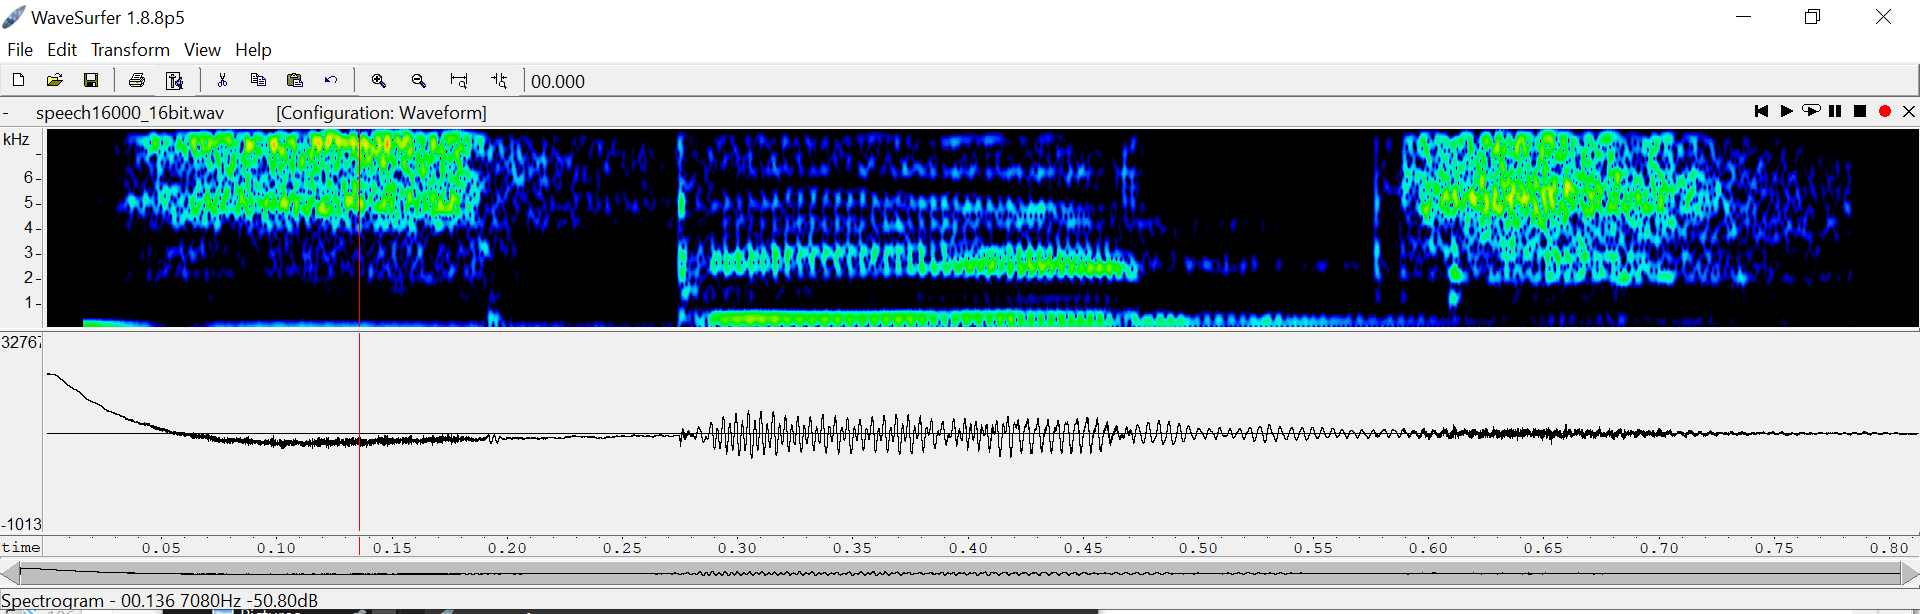

### Theory:

The number of bits that are needed to store the samples of speech signal is known as bit resolution. The bit resolution is characterized by the quantization levels - as the quantization levels are increased, the information stored in digital form is more close to the analog form; however, more storage space is required. There is thus a tradeoff between storage space and quantization levels.

### Procedure:

We will use a speech signal ("Speech") sampled at 16 khz and 16 bits/sample as the starting signal. This initial signal is procured via the software *Audacity. *We then plot its time plot for whole signal and frequency plots for each sound. To change the bits/sample, we write an algorithm which does this task, it will take the original 2^16 quantization levels and changes it to the 2^(no. of bits) quantization levels by checking if the original value lies between any of the new quantization levels and rounds it to the higher level of the new quantization levels. We then again plot the whole time signal and frequency spectrum of these signals with different bit resolution.

### Code and Plots:

**1. 16 kHz 16 bits/sample**

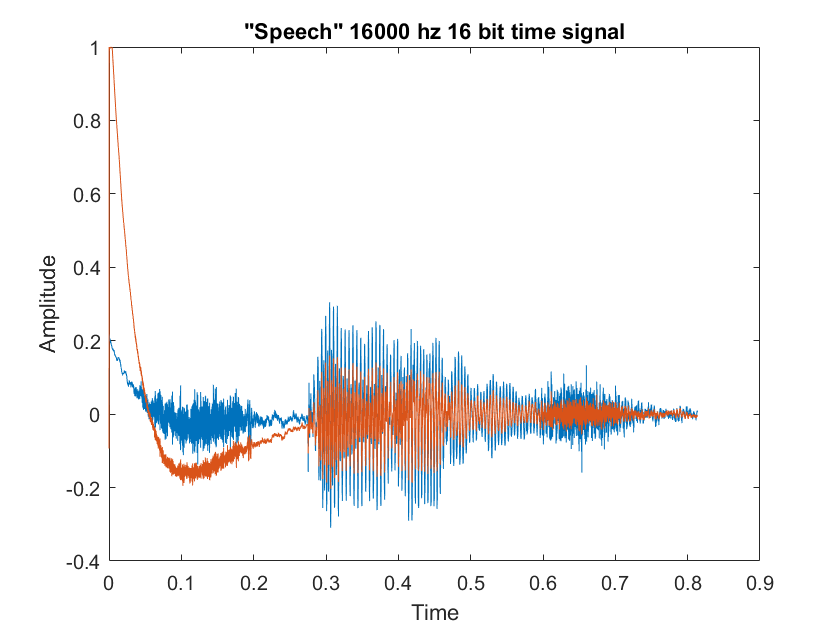

close all; clc; clear all;

[y,fs]=audioread('speech16000_16bit.wav'); 
sound(y, 16000);

% y = y(:,2); % Taking right channel

% "Speech" 
plot_time_signal(y, fs, '"Speech" 16000 hz 16 bit time signal'); 

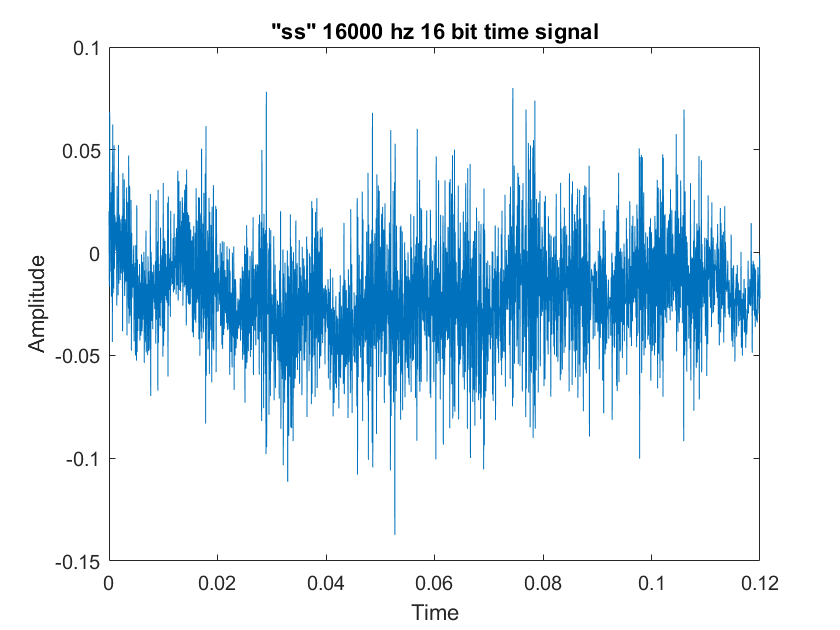


% ss (Fricative, Sibilant)
plot_time_signal(y(int64(0.07*fs):int64(0.19*fs)), fs, '"ss" 16000 hz 16 bit time signal');

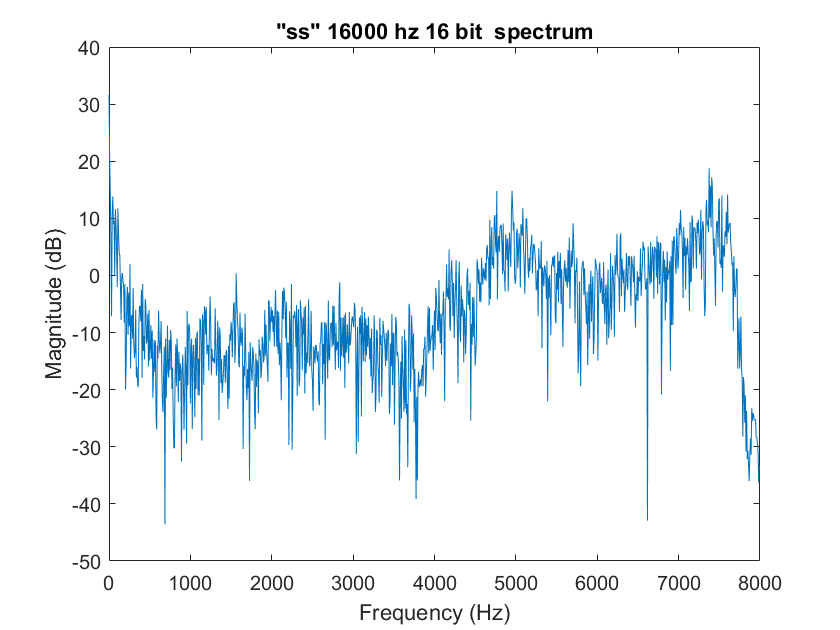

plot_freq_spectrum(y(int64(0.07*fs):int64(0.19*fs)), fs, '"ss" 16000 hz 16 bit  spectrum');

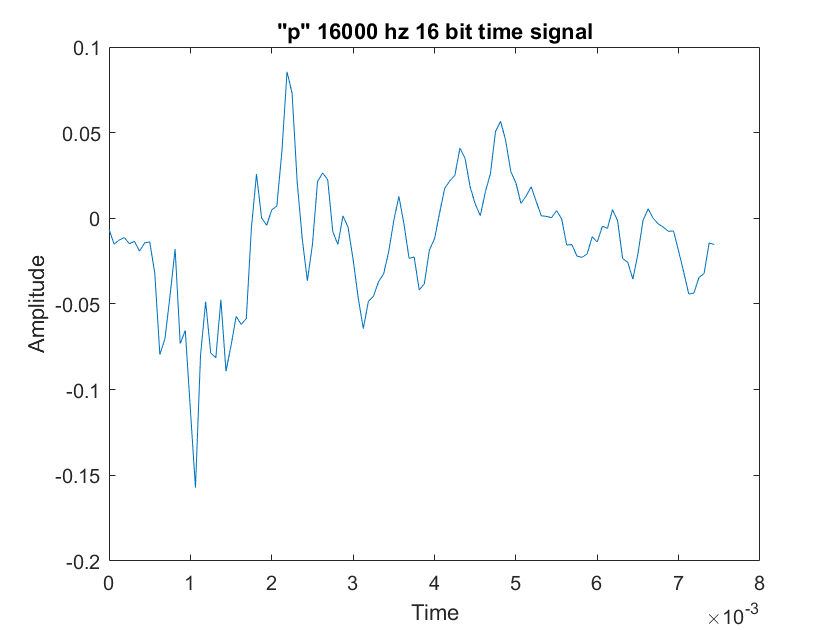


% p (UU, Plosives)
plot_time_signal(y(int64(0.2744*fs):int64(0.2818*fs)), fs, '"p" 16000 hz 16 bit time signal');

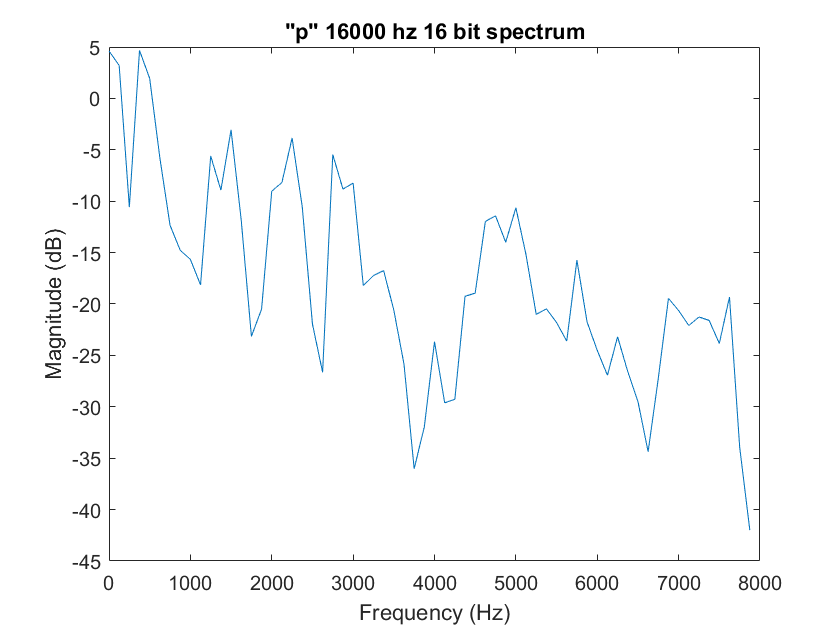

plot_freq_spectrum(y(int64(0.2744*fs):int64(0.2818*fs)), fs, '"p" 16000 hz 16 bit spectrum');

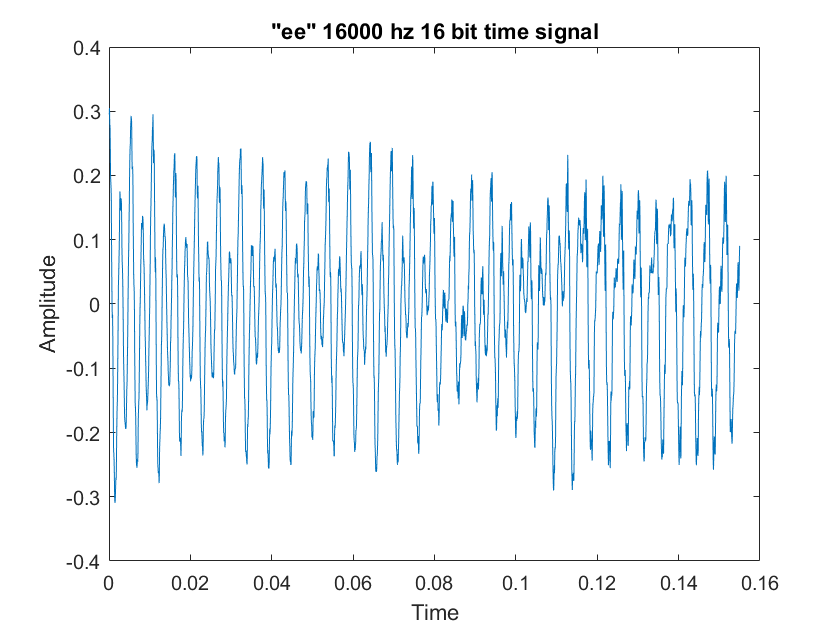


% ee (Vowel)
plot_time_signal(y(int64(0.305*fs):int64(0.460*fs)), fs, '"ee" 16000 hz 16 bit time signal');

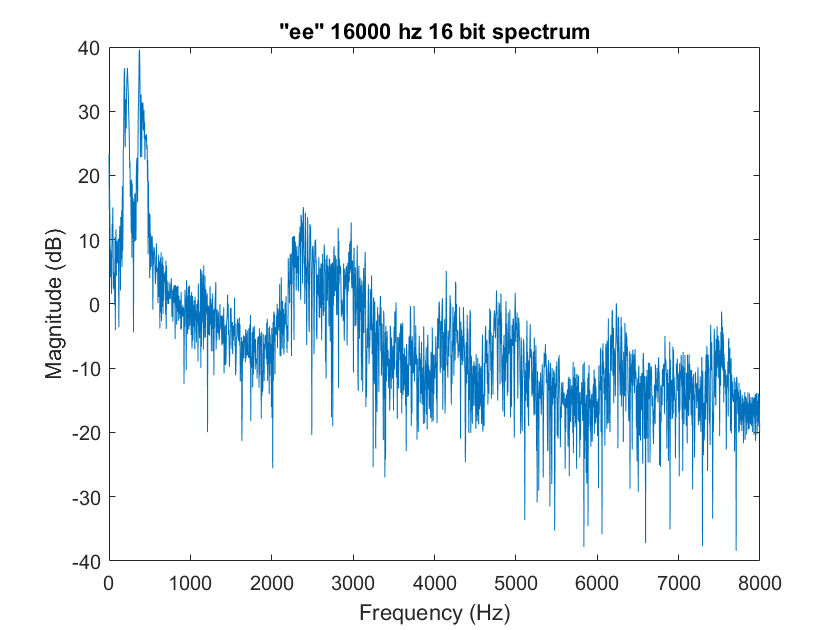

plot_freq_spectrum(y(int64(0.305*fs):int64(0.460*fs)), fs, '"ee" 16000 hz 16 bit spectrum');

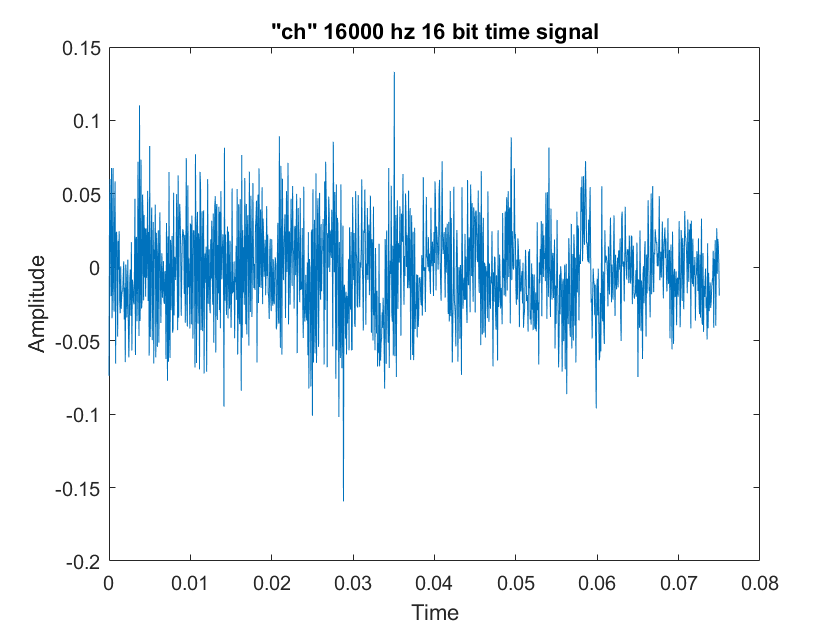


% ch (affricate)
plot_time_signal(y(int64(0.625*fs):int64(0.7*fs)), fs, '"ch" 16000 hz 16 bit time signal');

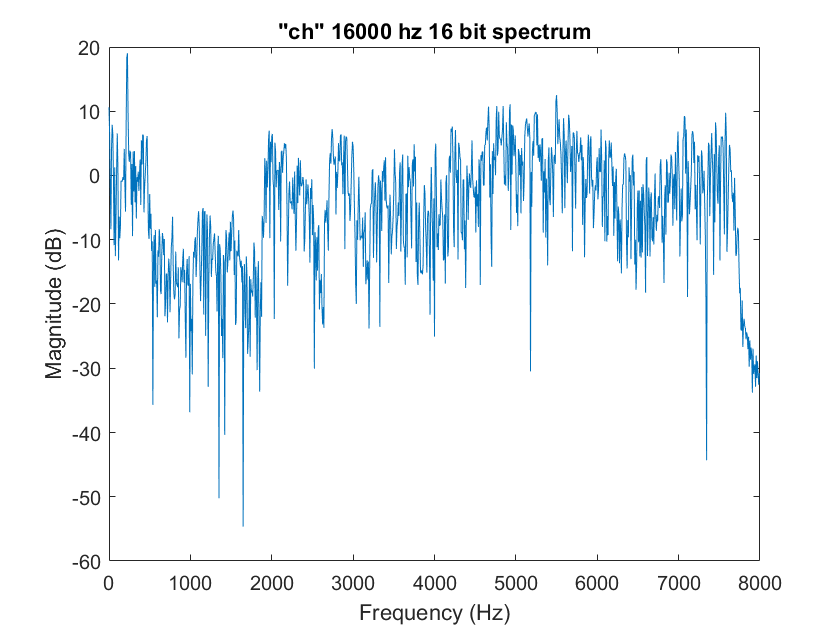

plot_freq_spectrum(y(int64(0.625*fs):int64(0.7*fs)), fs, '"ch" 16000 hz 16 bit spectrum');

**2. 8 bits/sample**

bit_res = 8;
no_of_quant_levels = 2^bit_res;
yaxis = (-1:2*(1/no_of_quant_levels):1-1/no_of_quant_levels);

y_2 = [];
for i = 1: length(y)
    for j = 2:length(yaxis)
        if(y(i) >=yaxis(j-1) && y(i) < yaxis(j))
            y_2 = [y_2; yaxis(j)];
            continue
        end
    end
end

sound(y_2, 16000);
plot_time_signal(y_2, fs, '"Speech" 16000 hz 8bit time signal'); 

% ss (Fricative, Sibilant)
plot_freq_spectrum(y_2(int64(0.07*fs):int64(0.19*fs)), fs, '"ss" 16000 hz 8 bit  spectrum');

% p (UU, Plosives)
plot_freq_spectrum(y_2(int64(0.2744*fs):int64(0.2818*fs)), fs, '"p" 16000 hz 8 bit spectrum');

% ee (Vowel)
plot_freq_spectrum(y_2(int64(0.305*fs):int64(0.460*fs)), fs, '"ee" 16000 hz 8 bit spectrum');

% ch (affricate)
plot_freq_spectrum(y_2(int64(0.625*fs):int64(0.7*fs)), fs, '"ch" 16000 hz 8 bit spectrum');

**Comments:** The word "speech" is audible and we are able to identify it, but the quality has reduced to a small extent.

**3. 4 bits/sample**

bit_res = 4;
no_of_quant_levels = 2^bit_res;
yaxis = (-1:2*(1/no_of_quant_levels):1-1/no_of_quant_levels);

y_3 = [];
for i = 1: length(y)
    for j = 2:length(yaxis)
        if(y(i) >=yaxis(j-1) && y(i) < yaxis(j))
            y_3 = [y_3; yaxis(j)];
            continue
        end
    end
end

sound(y_3, 16000);
plot_time_signal(y_3, fs, '"Speech" 16000 hz 4 bit time signal'); 

% ss (Fricative, Sibilant)
plot_freq_spectrum(y_3(int64(0.07*fs):int64(0.19*fs)), fs, '"ss" 16000 hz 4 bit  spectrum');

% p (UU, Plosives)
plot_freq_spectrum(y_3(int64(0.2744*fs):int64(0.2818*fs)), fs, '"p" 16000 hz 4 bit spectrum');

% ee (Vowel)
plot_freq_spectrum(y_3(int64(0.305*fs):int64(0.460*fs)), fs, '"ee" 16000 hz 4 bit spectrum');

% ch (affricate)
plot_freq_spectrum(y_3(int64(0.625*fs):int64(0.7*fs)), fs, '"ch" 16000 hz 4 bit spectrum');

**Comments:** A distorted and harsh "speech" sound is heard, although i was able to identify it partially, I would'nt recommend using this bit resolution. The fricatives ("ss")  are mostly inaudible, the affricates are partially audible. Plosives and vowels are partially distinguishable. 

**4. 1 bit/sample**

y_4 = [];
for i = 1: length(y)
        if(y(i) > 0 )
            y_4 = [y_4; 1];
        else
            y_4 = [y_4; 0];
        end
end

sound(y_4, 16000);
plot_time_signal(y_4, fs, '"Speech" 16000 hz 1 bit time signal'); 

% ss (Fricative, Sibilant)
plot_freq_spectrum(y_4(int64(0.07*fs):int64(0.19*fs)), fs, '"ss" 16000 hz 1 bit  spectrum');

% p (UU, Plosives)
plot_freq_spectrum(y_4(int64(0.2744*fs):int64(0.2818*fs)), fs, '"p" 16000 hz 1 bit spectrum');

% ee (Vowel)
plot_freq_spectrum(y_4(int64(0.305*fs):int64(0.460*fs)), fs, '"ee" 16000 hz 1 bit spectrum');

% ch (affricate)
plot_freq_spectrum(y_4(int64(0.625*fs):int64(0.7*fs)), fs, '"ch" 16000 hz 1 bit spectrum');

**Comments:** The distortion and harshness is very prominent, the word "speech", the fricative ("ss") is not even heard in this case, the other sounds are partially audible but with very bad quality/naturalness. 

### Observations: 

We see that as we reduce the bit resolution, the quality and intelligibility of the sounds reduces as quantity of the speech information is being reduced/quantized. We see that at 16 bit resolution, the quality and intelligibility is fairly good, and even in 8 bit resolution the frequency spectrums of each sound isnt vastly different though some distortions to the frequency components are observed. So 8 bit resolution is also a good enough bit resolution when storage is of more importance, with a slight tradeoff in quality and intelligibility. At 4 bit resolutions, the frequency spectrum for different sounds is different to that of the 16bit resolution signal, and hence is not a good bit resolution to use. Similary for 1 bit resolution, the frequency spectrums of the sounds are vastly different with only some frequency components matching the 16 bit resolution signal. 

### Function Definitions

function plot_time_signal(y, fs, title_name)
    plot((0:length(y)-1)/fs,y);
    xlabel("Time");
    ylabel("Amplitude");
    title(title_name);
end

function plot_freq_spectrum(x, fs, title_name)
    N = length(x);
    n = pow2(nextpow2(N)); % Transforming the length so that the number of samples is a power of 2. 
    f = fs*[0: n-1]/n;
    X_mags = 20*log10(abs(fft(x, n)));
    N_2 = ceil(n/2);
    plot(f(1:N_2), (X_mags(1:N_2)));
    xlabel('Frequency (Hz)')
    ylabel('Magnitude (dB)');
    title(title_name);
end